% Lab 8 OCTC matrices
format short eng
% Apply a 1mV test source at the terminals of Cpi resulting in Vpi = 1mV,
% and find the terminal current ix.  

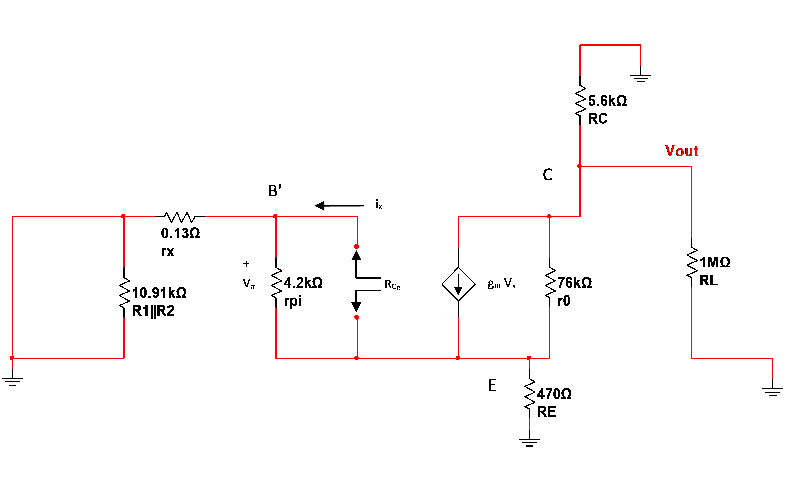

% A node voltage analysis of the small-signal equivalent circuit for C_pi
% yields the following 3x3 systetm:

A = [1      -1/0.13                               0;
     1       1/76e3+1/470                   -1/76e3;
     0       1/76e3           -1/76e3-1/1e6-1/5.6e3];
 
B = [238.095e-9+7.692e-3;
     238.095e-9+52e-6;
     52e-6];
 
C = A\B; % C(1)= ix

R_Cpi = 1e-3/C(1) % RCpi is 1 mV/ix.

R_Cpi =     19.6797e+000



% Apply a 1mA test source at the terminals of Cmu and find the terminal
% voltage, vx = vB'-vC.

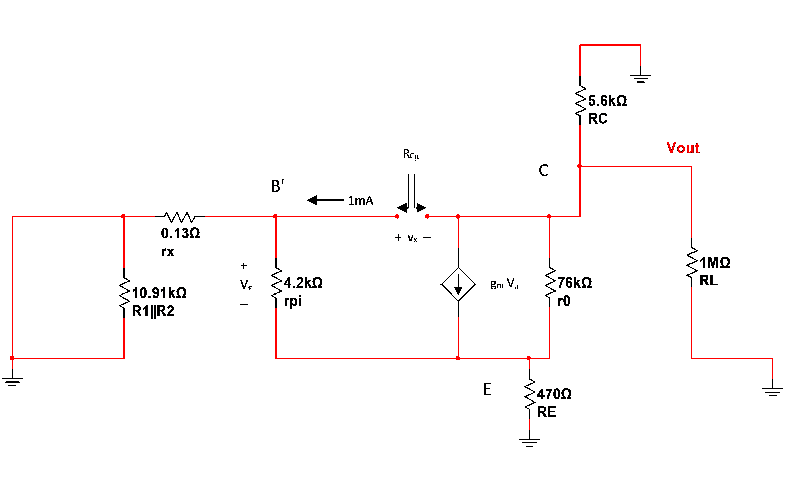

% A node voltage analysis of the small-signal equivalent circuit for C_mu
% yields the following 3x3 systetm:

A = [1/0.13+1/4.2e3   -1/4.2e3                                         0;
     1/4.2e3+0.052    -1/470-1/4.2e3-0.052-1/76e3                 1/76e3;
     0.052            -0.052-1/76e3                 1/76e3+1/1e6+1/5.6e3];
 
B = [1e-3;
     0;
     -1e-3];
 
C = A\B; % C(1)= vB' and C(3)= vC.

R_Cmu = (C(1)-C(3))/1e-3 % RCmu is vx/1mA = (VB'-vC)/1mA.

R_Cmu =      5.5527e+003



% Apply a 1V test source at the terminals of C1 resulting in VC = 1V, and
% find the terminal current ix.  

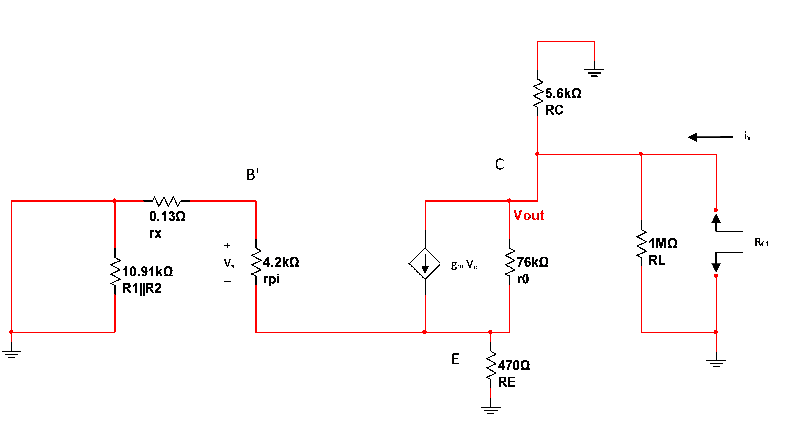

% A node voltage analysis of the small-signal equivalent circuit for C1
% yields the following 3x3 systetm:

A = [1/0.13+1/4.2e3   -1/4.2e3                      0;
     1/4.2e3+0.052    -1/470-1/4.2e3-0.052-1/76e3   0;
    -0.052             0.052+1/76e3                 1];
 
B =  [0;
     -13.158e-6;
      192.729e-6];
 
C = A\B; %C(3)= ix.

R_C1 = 1/C(3) % RC1 is 1V/ix.

R_C1 =      5.5511e+003



C_pi = 27e-12;
C_mu = 9e-12;
C1 = 100e-12;

f_H = 1/(2*pi)*1/(C_pi*R_Cpi + C_mu*R_Cmu + C1*R_C1)% OCTC estimate.

f_H =    262.7972e+003



No_scope =1/(2*pi)*1/(C_pi*R_Cpi + C_mu*R_Cmu) % Delete scope tau term.

No_scope =      3.1512e+006



Ten_x_probes = 1/(2*pi)*1/(C_pi*R_Cpi + C_mu*R_Cmu + 13e-12*R_C1)% 10x probe reduces C1 to about 13 pF.

Ten_x_probes =      1.2974e+006
